# Introduction to uDALES post-processing with MATLAB

This tutorial describes how to read and process facet data of the LES code uDALES using MATLAB. This tutorial introduces the `udbase` post-processing class. There are separate tutorials for processing field files and facet files.

The `udbase` post-processing class reads in most important input parameters, and contains a number of methods to load field and facet data.

**Field data:**

- **load_stat_xyt**. This method load the 1D slab- and time-averaged statistics from the file `xytdump.expnr.nc`. Several time-intervals may be present in the data.

- **load_stat_t**. This method loads the 3D time-averaged statistics from the file `tdump.expnr.nc`. Several time-intervals may be present in the data.

- **load_field**. This method loads instantaneous 3D data from the file `fielddump.expnr.nc`. Several output times may be present in the data.

- **load_slice**. This method loads instantaneous 2D slices of instantaneous 3D data from the file `Xslicedump.expnr.nc`. Several output times may be present in the data.

**Facet data:**

- **calculate_frontal_properties**. This method calculates the skylines, frontal areas and blockage ratios in the x- and y-direction.

- **plot_fac_type.** This method displays the type of surface for each facet.

- **assign_prop_to_fac**. This method assigns a property of the facet type to each of the facets, so it can be used for calculation and visualisation

- **plot_fac. **This method displays a surface variable on the mesh.

- **load_fac_momentum. **This method loads instantaneous momentum surface data from `fac.expnr.nc`. The first index is the facet id and second index is time.

- **load_fac_eb. **This method loads instantaneous surface energy balance data from `facEB.expnr.nc`. The first index is the facet id and second index is time.

- **load_seb. **This method loads all instantaneous surface energy balance terms. The first index is the facet id and second index is time.

- **load_fac_temperature. **This method loads instantaneous facet temperature data `facT.expnr.nc`. The first index is the facet id, the second is the layer index and the third index is time.

- **area_average_seb. **This method calculates the area-averaged surface energy balance from the facet surface energy balances obtained using `load_seb`.

- **area_average_fac. **This method performs area-averaging over (a selection of) the facets. The facet index is assumed to be the first index of the array.

- **time_average. **This method performs time-averaging on an array; where time is assumed to be the last index of the array.

- **convert_fac_to_field**. This method converts a facet variable to a density in a 3D field, so it can be used for post-processing (e.g. calculating distributed drag).

**The live matlab file of this tutorial can be found in the repository in the folder /docs/tutorial_mlx. **

## Initialising udbase

The starting point of this tutorial is that you have run a simulation and have merged the output files. If the simulations were performed on a HPC system, **we assume that you have copied the output directory to your own workstation**. Some of the netCDF (*.nc) files may be very large and you may only want to copy these if you plan to analyse the data.

The uDALES postprocessing class is called `udbase`. Typically, you will create a post-processing script in the output directory on your workstation, but it is also possible to have the output directory located in another directory. This is particularly useful if you are comparing several different simulations at the same time. Here, we will show how to use data from simulation 065 (`expnr=065) `that is located in a different directory from the one you are working in.

**Note that the uDALES/tools/matlab path must be added via the Set Path button in order to use the udbase class. Alternatively, it can be added using the addpath function inside the script (done here).**

% preamble
clear variables
close all

% add the uDALES matlab path
addpath('../matlab')

% create an instance of the udbase class
expnr = 065;
expdir = '../experiments/065';
sim = udbase(expnr, expdir);

The constructor can have a number of input parameters:

help udbase.udbase

  Class constructor.
 
 
  udbase(expnr, dapath, load_preprocdata) 
     expnr:                       experiment number
     dapath (optional):           path to the experiment
 
  Example:
    obj = udbase(expnr, '/path/experiments/../100');

    Documentation for udbase/udbase



The constructor of the `udbase` class reads in the following files:

- `namoptions.expnr. C`ontains the simulation input parameters.

- `xxx.stl.` Contains the urban geometry used for the simulation [optional]. 

Provided that `load_preprocdata` is not set to false, the constructor of the `udbase` class additionally reads the following files:

- `solid_(u,v,w,c).txt. `Contains the indices of the (u,v,w,c)-volumes occupied by buildings.

- `facets.inp`. Contains information about the facet wall type and surface normal.

- `factypes.inp`. Contains information about the properties of the wall types.

- `facetarea.inp`. Contains information about the facet areas.

- `fluid_boundary_(u,v,w,c).txt`. Contains information about the fluid cells associated with facet sections.

- `facet_sections_(u,v,w,c).txt`. Information about facet section area, distance and flux point.

## Accessing simulation properties

To view all simulation input parameters, simply type

sim

sim =   udbase with properties:

              expnr: '065'
               geom: [1×1 udgeom.udgeom]
                 xm: [64×1 double]
                 ym: [64×1 double]
                 zm: [64×1 double]
                 xt: [64×1 double]
                 yt: [64×1 double]
                 zt: [64×1 double]
                 dx: 1
                 dy: 1
                dzm: [64×1 double]
                dzt: [64×1 double]
                 Su: [64×64×64 logical]
                 Sv: [64×64×64 logical]
                 Sw: [64×64×64 logical]
                 Sc: [64×64×64 logical]
               facs: [1×1 struct]
           factypes: [1×1 struct]
             facsec: [1×1 struct]
          nbndpts_w: 5164
          fieldvars: ''v0,th,qt,u0,w0''
          ladaptive: 1
           sinkbase: 32
             ltdump: 0
           trestart: 51000
          igrw_damp: 0
         stl_ground: 1
               facT: 301
          i

For a complete list of parameters and their meaning, please consult the pre-processing documentation. Some commonly used parameters are 

- `xlen`, `ylen` and `zsize `that represent the domain size  

- `itot`, `jtot` and `ktot `that represent the total number of grid cells

To access a parameter directly, use the syntax `object.prop`. To access the domain length in x-direction, use

sim.xlen

ans = 64

The geometry stored in the STL file, if present, has been also loaded, which can be visualised using the method below. This method will produce an error if STL file does not exist or been loaded.

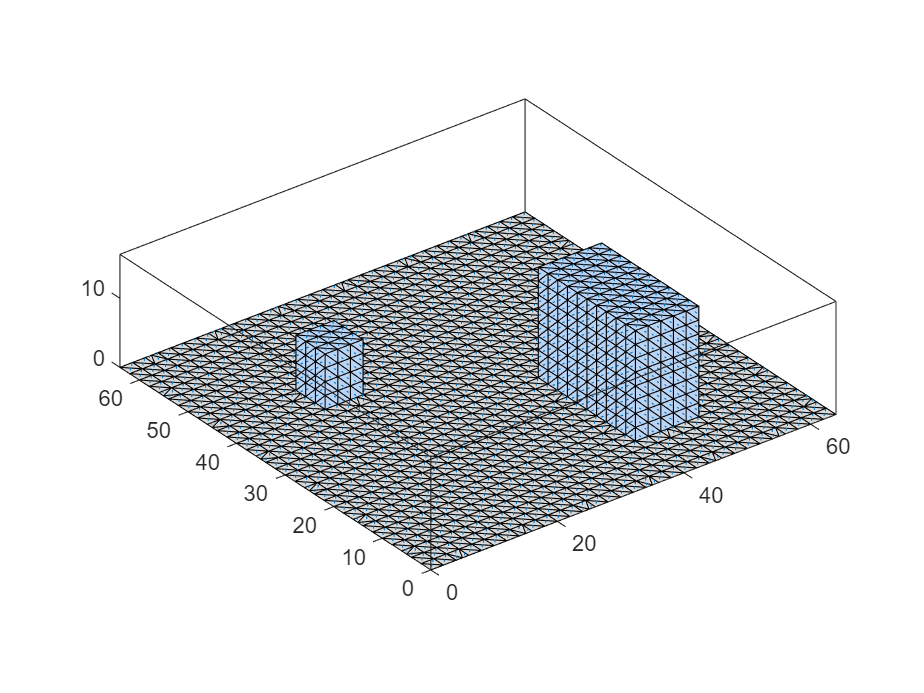

sim.geom.show();